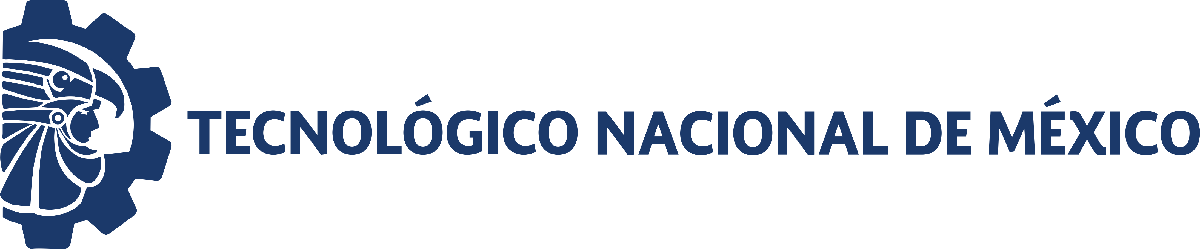                                 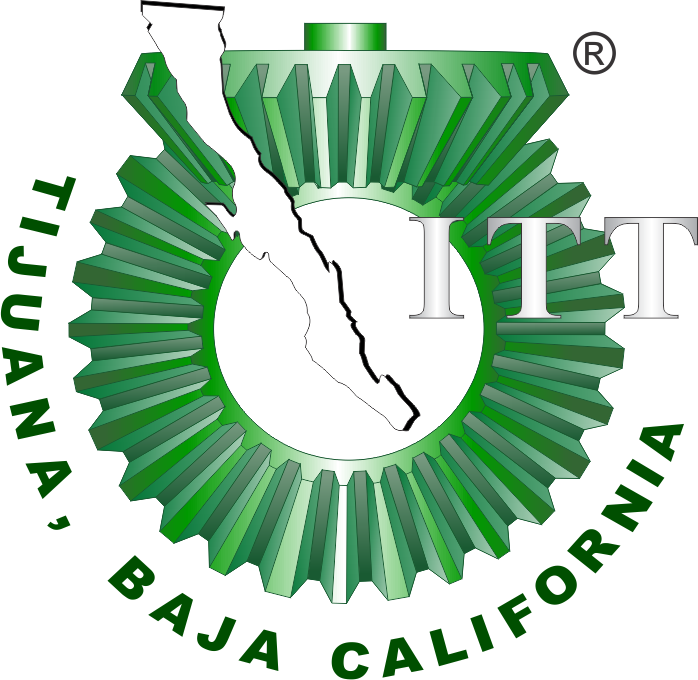

# Práctica 4: Sistema endrocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

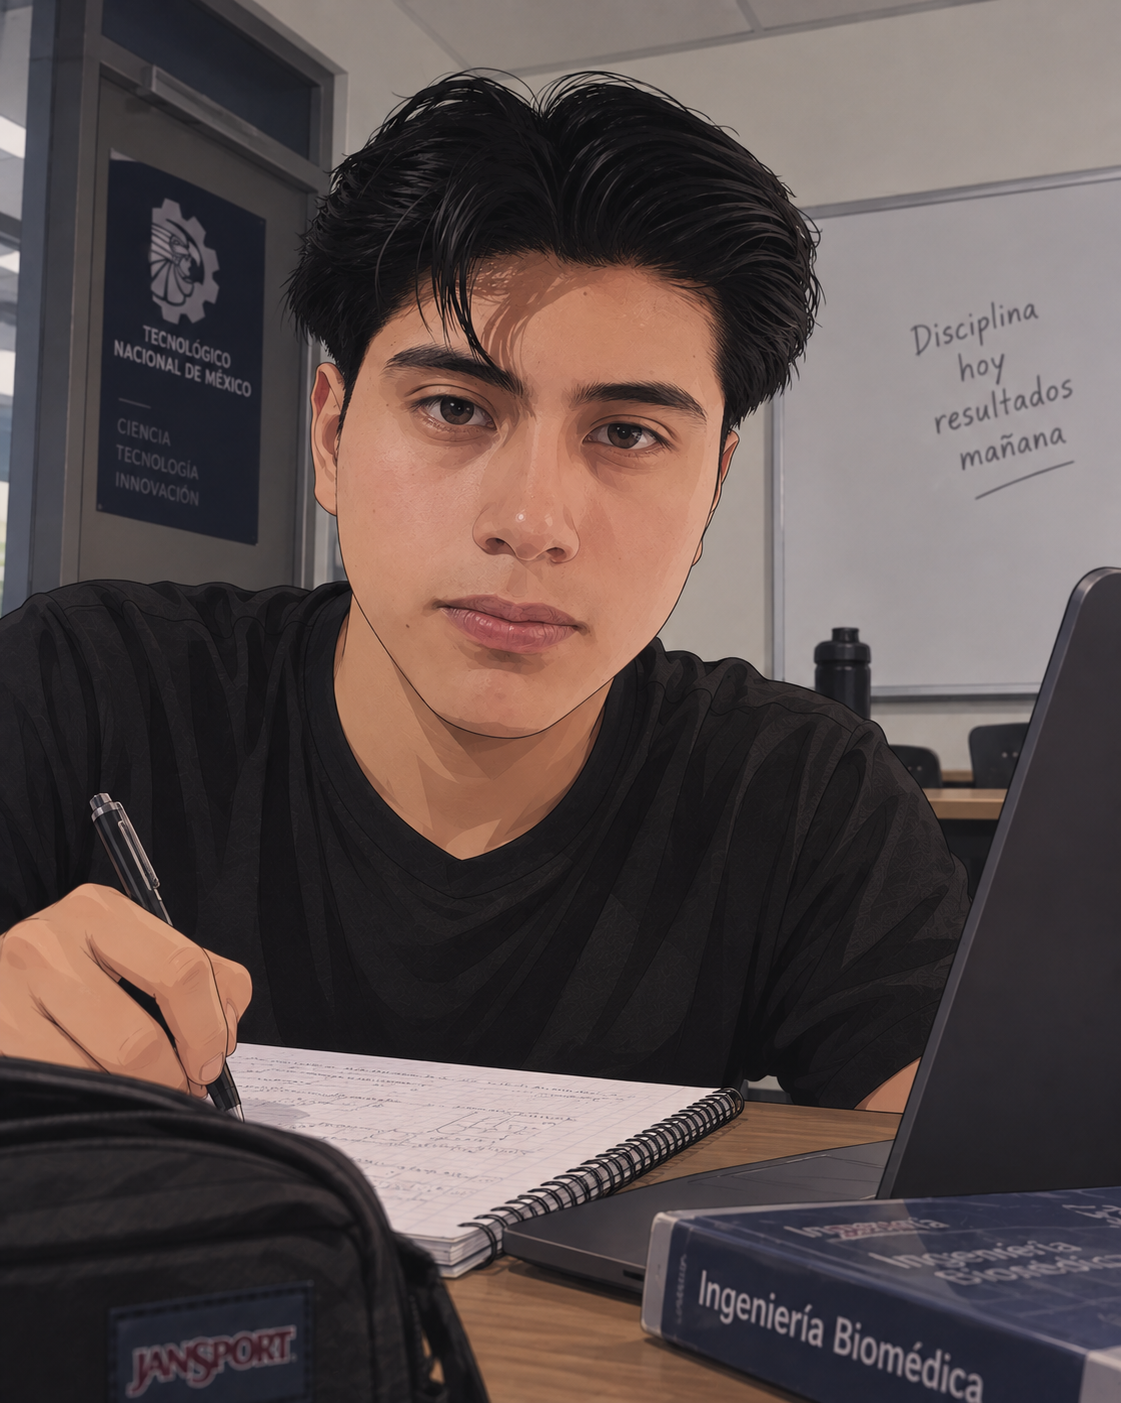

Nombre del alumno: Bautista Paz Jesus Geovanny

Número de control: 23212181

Correo institucional: l23212181**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistemap5')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('sistemap5',parameters);



## Respuesta del sistema

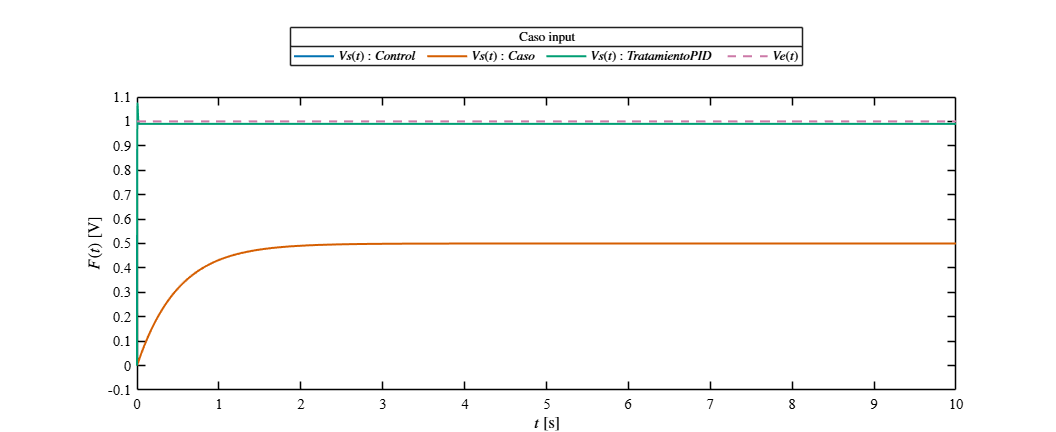



plotsignals(x.control,x.CE,x.FT,x.PID,x.Ve,'Caso')

## Funcion: Respuestas de la simulacion




function plotsignals(t,s,s1,s2,v1,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,11,4.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    
    clr1 = [0, 114, 178]/255;
    clr2 = [213, 94, 0]/255;
    clr3 = [0, 158, 115]/255;
    clr4 = [204, 121, 167]/255;

    order = [clr1;clr2;clr3;clr4]; colororder(order)

    if signal == "Caso"
        plot(t.Time, t.Data, '-', ...
             t.Time, s1.Data, '-', ...
             t.Time, s2.Data, '-', ...
             t.Time, v1.Data, '--', ...
             'LineWidth',1.5,'MarkerSize',5, ...
             'MarkerIndices',1:1e3:length(t.Time));

        l = legend('$Vs(t): Control','$Vs(t): Caso', ...
            '$Vs(t): Tratamiento PID','$Ve(t)$');
    end

    set(l,'interpreter','latex','location','northoutside','orientation','horizontal')
    title(l,[signal,' input'])

    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$F(t)$ [V]','interpreter','latex')

    xlim([0 10]); xticks(0:1:15)
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

    set(gcf,'Color','white')
    set(gca,'Color','white','XColor','black','YColor','black')
    set(l,'Color','white','TextColor','black')

   
   

end



